# **INICIALIZANDO MODELO**

m = 1.0;
M = 5.0;
L = 2.0;
g = -10.0;
d = 1.0;

% Pendulum up (s=1)‍
s = -1; 

% MATRIZES STATE SPACE
A = [0          1                0 0;
     0       -d/M           -m*g/M 0;
     0          0                0 1;
     0 -s*d/(M*L) -s*(m+M)*g/(M*L) 0];

B = [0; 1/M; 0; s*1/(M*L)];

C = [1, 0, 0, 0];

ob = obsv(A,C);


# **ENCONTRANDO MELHOR MEDIDAS DE `X`**

% Which measurements are best if we omit `x`
D = zeros(size(C,1), size(B,2));

Vd = 0.1*eye(4); % disturbance covariance
Vn = 1;          % noise covariance

BF = [B, Vd, 0*B]; % augment inputs with disturbance and noise

sysC = ss(A, BF, C, [0 0 0 0 0 Vn]);

sysFullOutput = ss(A,BF,eye(4), zeros(4, size(BF,2)));
% system with full state output, disturbance, no noise

# **FILTRO DE KALMAN**

%% Build Kalman filter
% [Kf,P,E] = lqe(A,Vd,C,Vd,Vn);
Kf = (lqr(A', C', Vd, Vn))';

sysKF = ss(A-Kf*C, [B Kf], eye(4), 0*[B Kf]);

# **ESTIMATIVAS PARA POSICAO `DOWN`**

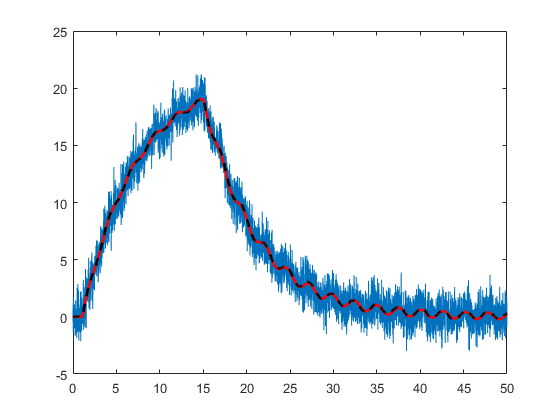

%% Estimate linearized system in `down` position (Gantry crane)
dt = 0.01;
t = dt:dt:50;
t = t - t(1);

uDIST  = randn(4,size(t,2));
uNOISE = randn(size(t));
u = 0*t;
u(100:120) = 100; % impulse
u(1500:1520) = -100; % impulse

uAUG = [u; Vd*Vd*uDIST; uNOISE];

[y, t] = lsim(sysC, uAUG, t);
plot(t,y);

[xtrue, t] = lsim(sysFullOutput, uAUG, t);
hold on;
plot(t, xtrue(:,1), 'r', 'linew', 2);

%% Kalman filter estimate
[x,t] = lsim(sysKF, [u;y'], t);
plot(t,x(:,1), 'k--', 'linew', 2);

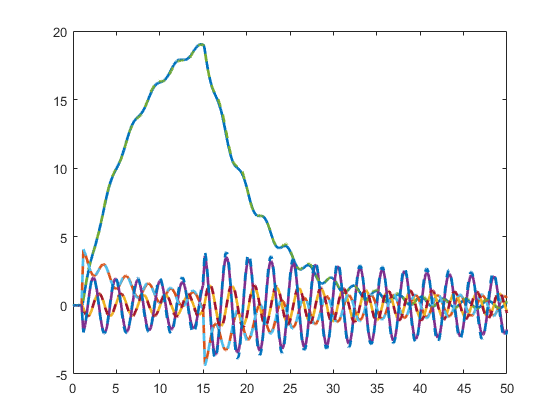


%% 
figure
plot(t,xtrue, '-', t, x, '--', 'linew', 2);